# Wheel Turning Speed Analysis

In the experiment reported by [Steinmetz et al, 2019 in Nature](https://www.nature.com/articles/s41586-019-1787-x), the mice perform a discrimination task where that had to find out which stimuli (left vs right) has the higher contrast. And they report their  decision by steering a wheel such that the stimuli with the higher  contrast moves to the center screen.

**Analysis Goals**

In this notebook we will be analyzing the speed at which the mouse turned the wheel to report their decision.

**Learning Goals**

- Filter data in a table

- Produce line plots

- Make formatted print statements

## Visualising Wheel Turning Speed

In this section we will plot the speed at which the mouse turned the  wheel in every trial. 

The experimental data contains the wheel speed over time, across all  trials. A positive turning speed means that the wheel is being moved to  the right, while a negative speed tells us the wheel is being moved to  the left. When the wheel is not being moved at all, the turning speed is zero. 

The wheel speed data is binned in bins of 10ms, meaning the difference in time between each datapoint is 10ms.

data = readtable("data/Cori_14-12-2016_wheel.xml");

**Example Exercise**

Plot the wheel speed against time for trial 7 

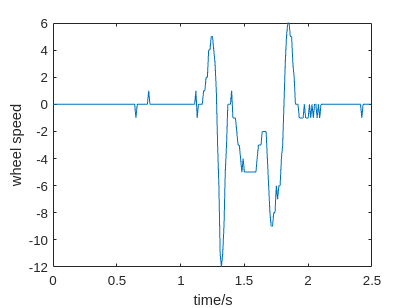

plot_data = data{data.trial==7,'wheel_speed'};
time_bins = 0:0.01:2.49; % times in s
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for trial 99

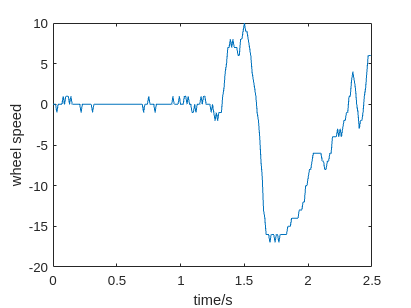

plot_data = data{data.trial==99,'wheel_speed'};
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Plot the wheel speed against time for the last trial (ie. the largest trial number) in the data. There are many ways to do this!

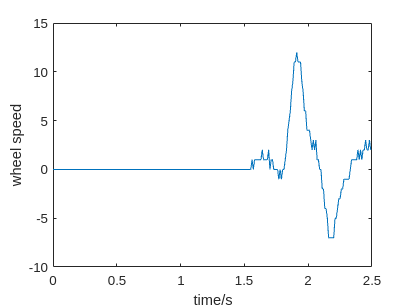

plot_data = data{data.trial==max(data.trial),'wheel_speed'};
plot(time_bins,plot_data)

xlabel('time/s')
ylabel('wheel speed')

Make a figure showing the wheel speeds of both trials 26 and 27. **Hint** - you will need to use the following pattern: 

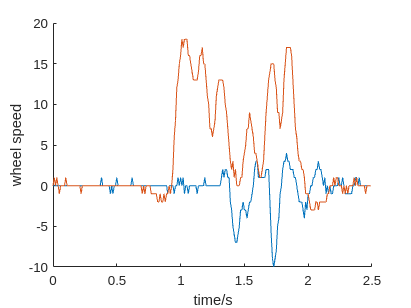

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t27)
plot(time_bins,plot_data_t26)

xlabel('time/s')
ylabel('wheel speed')
hold off

Recreate the above plot adding legend labels to the lines

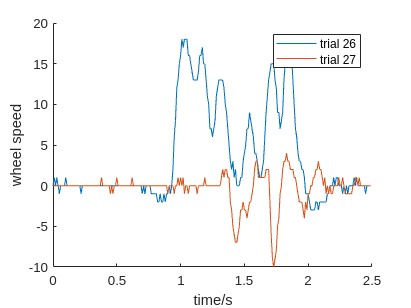

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t26, "DisplayName","trial 26")
plot(time_bins,plot_data_t27,"DisplayName","trial 27")

xlabel('time/s')
ylabel('wheel speed')
legend()
hold off

Looks good! But the legend does obscure the data. Change the position of the legend. **Hint** run 

to view an explanation of possible options that can be given to` legend()`

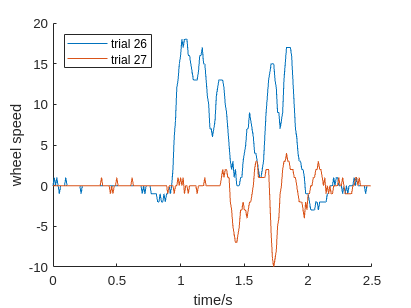

plot_data_t26 = data{data.trial==26,'wheel_speed'};
plot_data_t27 = data{data.trial==27,'wheel_speed'};

clf
hold on
plot(time_bins,plot_data_t26, "DisplayName","trial 26")
plot(time_bins,plot_data_t27,"DisplayName","trial 27")

xlabel('time/s')
ylabel('wheel speed')
legend("Location", "northwest")
hold off

## Describing Data with Metrics: Determining Turning Direction

Data analysis is all about making sense of data. Statistics like  averages is one example of this. Such measures can help us minimise the  amount of data that we need to think about and allow to answer more  generic questions. In the context of the wheel speed data that we have  been working on so far, a natural question is: **which way did the subject turn the wheel?**

In this section, we will be using aggregation methods such as `mean()` combined with filtering to further analyze the wheel speed data for  instance to only look at trials in which the wheel was turned to the  left.

What is the size of the wheel speed data?

size(data.wheel_speed)

ans =    214   250


That means that we have 214 trials and each trial has 250 datapoints of wheel speed. 

Say if we want to find the average wheel speed for each trial, we would then have 214 values

What is the size of the result `mean(data.wheel_speed)`?

size(mean(data.wheel_speed))

ans =      1   250


By default MATLAB calculates the mean across the columns of the table. We are interested however in the mean across the rows. 

This is given by changing the axis across which the mean is calculated. By default the axis is 1, like this

mean(data.wheel_speed,1)

ans =     0.1028    0.0701    0.0701    0.0280    0.0187    0.0187   -0.0234    0.0467    0.0047    0.0047   -0.0047   -0.0093   -0.0327    0.0374    0.0047   -0.0093    0.0093    0.0187         0   -0.0140    0.0280    0.0140   -0.0047    0.0047    0.0140         0   -0.0140   -0.0047   -0.0047    0.0093         0    0.0140   -0.0140   -0.0093    0.0140         0         0   -0.0093   -0.0093         0   -0.0140         0    0.0187   -0.0093    0.0140   -0.0047   -0.0093         0         0    0.0374


**Exercises**

Calculate the mean wheel speed for each trial. Name the result `mean_wheel_speeds`

mean_wheel_speeds = mean(data.wheel_speed,2);

Make a new column in data "mean_wheel_speed" which holds the values of  `mean_wheel_speeds`

data.mean_wheel_speed = mean_wheel_speeds;

In the next few steps, we will visualize the data for which the average wheel speed was greater that 0.

First, filter `data` for where the mean wheel speed is greater than 0. 

data(data.mean_wheel_speed>0,:)

ans = 116×11 table
    trial    active_trials    feedback_type    response_type     gocue     response_time    feedback_time    mouse     session_date    wheel_speed     mean_wheel_speed
    _____    _____________    _____________    _____________    _______    _____________    _____________    ______    ____________    ____________    ________________

      1            1                1                1           1.0272        1.1502           1.1868       "Cori"    14-Dec-2016     1×250 double         4.376      
      3            1                1                1          0.82521       0.94929          0.98602

Find the wheel speeds where the mean wheel speed is greater than 0. Call this variable `mean_speed_gtr_zero. `We will judge that when the mean wheel speed is greater than 0, the wheel was turned to the right.

mean_speed_gtr_zero = data{data.mean_wheel_speed>0,"wheel_speed"};

Plot `mean_speed_gtr_zero` against `time_bins`

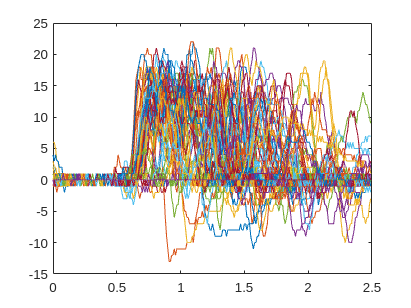

plot(time_bins, mean_speed_gtr_zero)

Compare the plot above to a plot of wheel speed against time for all trials. **Hint **- `my_table{:, "column_A"} `retrieves all rows of column_A from a table 

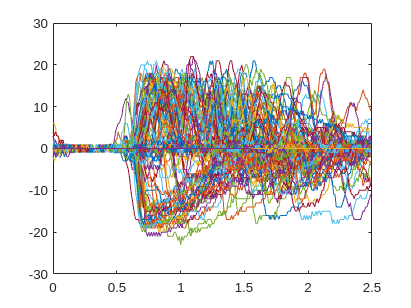

plot(time_bins, data{:,"wheel_speed"})

Find the wheel speed data for when the mean speed was less than 0

mean_speed_less_zero = data{data.mean_wheel_speed<0,"wheel_speed"};

Plot the wheel speed against time for this data

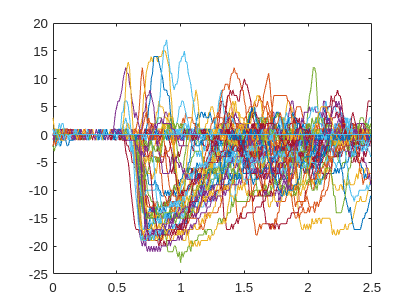

plot(time_bins, mean_speed_less_zero)

We will not use a different criteria to determine the turning direction. Now we will say that whenever the maximum wheel turning speed was greater than 10, the wheel was turned to the right.

Calculate the maximum wheel turning speed of each trial. Remeber to take the maximum over the correct axis.

max(data.wheel_speed,[],2 )

ans =     19
     5
    14
     7
    18
    14
     6
     6
     7
    20


Create a new column in `data `called `max_speed` which contains the maximum wheel turning speed for each trial

data.max_speed = max(data.wheel_speed,[],2);

Find the wheel speeds where the maximum wheel speed is greater than 10. Call this variable `max_speed_gtr_10 `

max_speed_gtr_10 = data{data.max_speed>10, "wheel_speed"};

Plot `max_speed_gtr_10` against `time_bins`

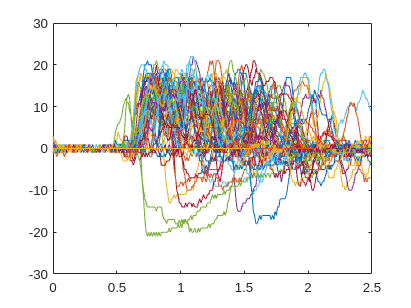

plot(time_bins, max_speed_gtr_10)

## Result Validation Using Print Statements

In programming, print functions are integral for outputting  human-readable results. In this section we will use print statements to  compare different metrics to determine the wheel turning direction, and  produce cleanly formatted sentences

We have two metrics to determine the wheel turning direction:

- when the mean wheel speed is greater than 0 -> the wheel was turned to the right

- when the maximum turning speed is greater than 10 -> the wheel was turned to the right

Luckily, the dataset authors have also provided information in the dataset  that specifies when they considered the turn to be left, right, or no  turn. This information is in the `response_type` variable. 

A `response_type` of:

-  1  :  corresponds to a right turn

- −1:  corresponds to a left turn

-  0  :   corresponds to no turning at all

Let's compare our metrics for determining the turning direction with the information provided by the dataset authors.

**Example Exercise**

 Print the value of variable `var_a` using a format string.

var_a = 33;
fprintf("the value of var_a is %d",var_a)

the value of var_a is 33

**Exercises**

Print the number of trials where the mean speed is less than zero using a format string.

num_trials_mean_less_0 = length(data{data.mean_wheel_speed<0,"trial"});
fprintf("The number of trials where the mean speed is less than zero is %d", num_trials_mean_less_0)

The number of trials where the mean speed is less than zero is 90

Print the number of trials where the mean speed is equal to zero.

num_trials_mean_eq_0 = length(data{data.mean_wheel_speed==0,"trial"});
fprintf("%d trials had a mean speed of zero", num_trials_mean_eq_0)

8 trials had a mean speed of zero

Print the percentage of trials where the mean speed is equal to zero.

perc_value = 100* num_trials_mean_eq_0 /height(data);
fprintf( "%d of percent trials had a mean speed of zero", perc_value)

3.738318e+00 of percent trials had a mean speed of zero

Are there too many decimal points in that number? We can apply rounding  to 4 decimal places by writing the print statement like so:

Display the percentage of trials with zero mean speed rounded to 3 decimal places.

fprintf( "%.3f percent of trials had a mean speed of zero", perc_value)

3.738 percent of trials had a mean speed of zero

Now let's move on to comparing the turning direction of our  predictions with those of the dataset authors, Steinmetz et. al. We will be focusing on the **right turns**.

Find the trial numbers of the table `data `where the response_type is 1. Call this `steinmetz_trials`.

steinmetz_trials = data(data.response_type ==1,"trial");

Find the trial numbers of the table data where the mean wheel speed is greater than 0. Call this `mean_gtr_0_trials`

mean_gtr_0_trials = data(data.mean_wheel_speed>0 ,"trial");

We will now determine the level of agreement by assessing how similar the two sets of trial numbers are.

Use the` ismember` function to determine how many elements in `mean_gtr_0_trials` are also in `steinmetz_trials`.

sum(ismember(steinmetz_trials, mean_gtr_0_trials))

ans = 67

ans = 67

ans = 71

ans = 0.9437

Summarise the percentage of agreement between us and the dataset authors with a formattted print statement

perc_val = 100* sum(ismember(steinmetz_trials, mean_gtr_0_trials))/height(steinmetz_trials);
fprintf("There is a %.2f percent agreement", perc_val)

There is a 94.37 percent agreement

Now we will make the same assessment but using the criteria that a right turn is made when the maximum wheel speed is greater than 10. 

Calculate the trial numbers where the maxmium wheel speed is greater than 10

data(data.max_speed>10, "trial")

ans = 80×1 table
    trial
    _____

      1  
      3  
      5  
      6  
     10  
     11  
     12  
     13  
     14  
     15  
     19  
     22  
     23  
     25  
     26  
     29  


Summarise the agreement between this method and the dataset authors

max_gtr_10_trials = data(data.max_speed>10, "trial");
perc_val = 100* sum(ismember(steinmetz_trials, max_gtr_10_trials))/height(steinmetz_trials);
fprintf("There is a %.2f percent agreement", perc_val)

There is a 90.14 percent agreement

Which method do you think is more accurate for determining the turning direction, and why? 

wd = steinmetz_2016_12_14_Cori.Variables(1,4).Value;

Unable to resolve the name 'steinmetz_2016_12_14_Cori.Variables'.


wheel_speed = reshape(wd', 1,[])';
trials = steinmetz_2016_12_14_Cori.Variables(1,3).Value
trials_flattened = reshape(repmat( trials,1,height(wd))', 1,[])';

time = repmat([0.01:0.01:2.5],1,length(trials))';

mydata = table(wheel_speed,trials_flattened ,time)

height(wd)

file="/home/ben/ibots/iBOTS-Tools/workshops/matlab-workshop-1/plan/day2/data/steinmetz_2016-12-14_Cori.nc"

wheel_speed = ncread(file, 'wheel');
wheel_speed = reshape(wd', 1,[])';

trials = ncread(file, 'trial');
trials_flattened = reshape(repmat( trials,1,height(wheel_speed))', 1,[])';

time = repmat([0.01:0.01:2.5],1,length(trials))';

mydata = table(wheel_speed,trials_flattened ,time)